clear; clc; close all;
sub_slc     = 2;
ses_slc     = 1:2;

% manage path
cur_dir      = pwd;
[project_dir, ~]= fileparts(fileparts(cur_dir));
out_dir      = fullfile(cur_dir, 's1Fig');
addpath(genpath(fullfile(project_dir,'func')))
data_dir     = fullfile(project_dir, 'data','biLoc');
if ~exist(out_dir,'dir') mkdir(out_dir); end

% organize data
[org_resp, org_conf, org_err, ExpInfo, org_sigVs] = org_data(sub_slc,ses_slc,'biLoc');

% organize by discrepancy
aud_locs = ExpInfo.speakerLocPixel(ExpInfo.audIdx);
conf_by_diff = org_by_diffs(org_conf, aud_locs); % {diff} cue x reliability x rep
sigV_by_diff = org_by_diffs(org_sigVs, aud_locs); % {diff} cue x reliability x rep
% conditions
seq         = ExpInfo.randAVIdx;
audIdx      = ExpInfo.audIdx;
visIdx      = ExpInfo.visIdx;
cueIdx      = ExpInfo.cueIdx;
visReliIdx  = ExpInfo.visReliIdx;
num_rep     = ExpInfo.nRep;
cue_label   = {'Post-cue: A','Post-cue: V'};
rel_label   = {'High visual reliability','Low visual reliability'};
vis_locs    = round(ExpInfo.targetPixel);
diffs       = zeros(length(aud_locs), length(vis_locs));
for i = 1:length(aud_locs)
    for j = 1:length(vis_locs)
        diffs(i, j) = aud_locs(i) - aud_locs(j);
    end
end
diff_locs   = unique(abs(diffs))';

lw = 2;
fontSZ = 15;
titleSZ = 20;
dotSZ = 80;
clt = [30, 120, 180; % blue
    227, 27, 27;  % dark red
    repmat(125, 1, 3)]./255;
%     251, 154, 153]./255; % light red

figure; hold on

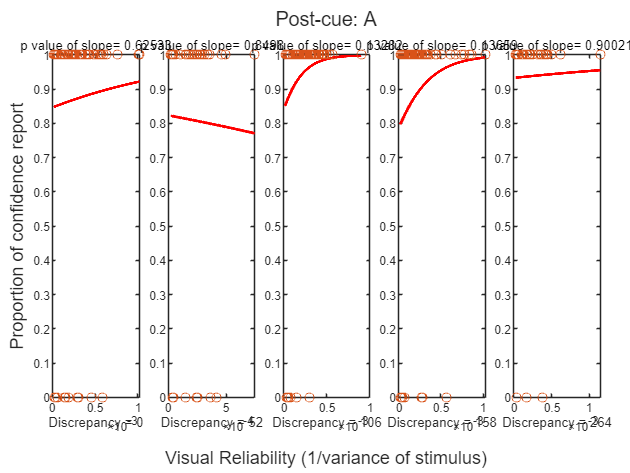

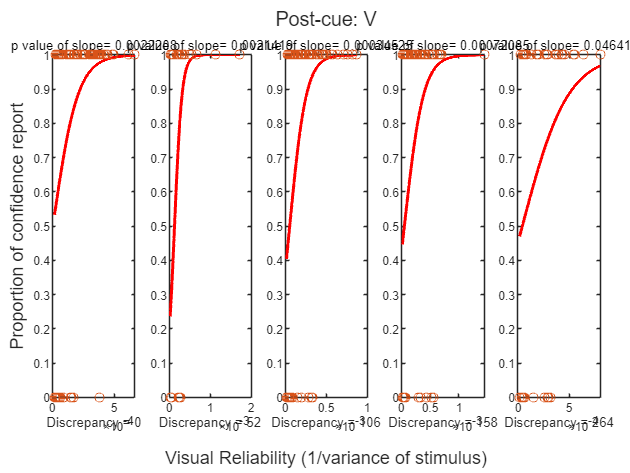

for cue = 1:numel(cueIdx)
    % nexttile
    % subplot(2,1,cue)
    % hold on
    % for rel = 1:numel(visReliIdx)
    [p_conf, se_conf] = deal(NaN(1, numel(diff_locs)));
    figure
    t = tiledlayout(1, 5);
    xlabel(t, 'Visual Reliability (1/variance of stimulus)');
    ylabel(t, 'Proportion of confidence report');
    title(t,cue_label{cue})
    t.TileSpacing = 'compact';
    t.Padding = 'compact';
    for diff = 1:numel(diff_locs)
        nexttile
        i_conf = squeeze(conf_by_diff{diff}(cue, :, :))';
        i_relV = 1./(squeeze(sigV_by_diff{diff}(cue, :, :))').^2;
        i_conf = i_conf(:);
        i_relV = i_relV(:);

        % subplot(1,5,diff)
        mdl = fitglm(i_relV, i_conf, 'Distribution', 'binomial');
        pValues(:,diff) = mdl.Coefficients.pValue;

        % Generating a range of values for prediction
        org_err_range = linspace(min(i_relV), max(i_relV), 1000)';
        % Predicting probabilities using the logistic regression model
        predicted_conf = predict(mdl, org_err_range);

        % Plotting the model prediction
        plot(org_err_range, predicted_conf, 'r-', 'LineWidth', 2);
        hold on
        scatter(i_relV,i_conf)
        hold off
        p = sum(i_conf)/numel(i_conf);
        p_conf(diff) = p;
        se_conf(diff) = sqrt((p*(1-p))/numel(i_conf));
        xlabel(['Discrepancy = ' num2str(diff_locs(diff))])
        title(['p value of slope= ' num2str(pValues(2,diff))])
    end
    % plot(diff_locs, p_conf, 'Color',clt(rel+1,:))
    % xlabel(f,'Visual Reliability (1/variance)');
    % ylim([0, 1])
    % end
    % sgtitle(cue_label{cue})
    % xticks(diff_locs)
end

% legend(rel_label, 'Location', 'eastoutside');